# Laborator 6

## Aplicația 1

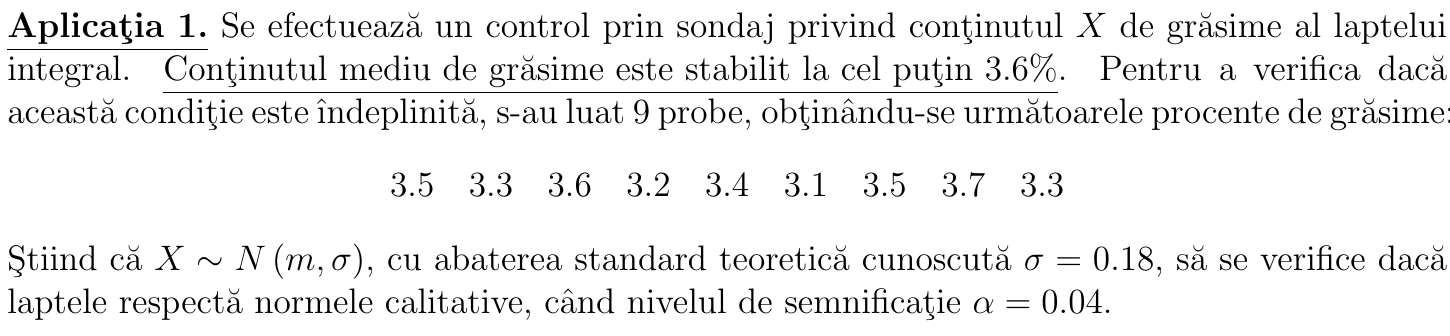

X = [3.5 3.3 3.6 3.2 3.4 3.1 3.5 3.7 3.3];
sigma = 0.18;
m_0 = 3.6;
alpha = 0.04;
tail = -1;
[h, ~, ~, zval] = ztest(X, m_0, sigma, alpha, tail);
if h == 0
    fprintf('Se acceptă ipoteza H_0.')
end
if h == 1
    fprintf('Se respinge ipoteza H_0.')
end

Se respinge ipoteza H_0.

Din **ztest**, **h = 1**, deci ipoteza $H_0$ se respinge. Se acceptă ipoteza $H_1$, deci conținutul mediu de grăsime este sub 3.6%.

## Aplicația 2

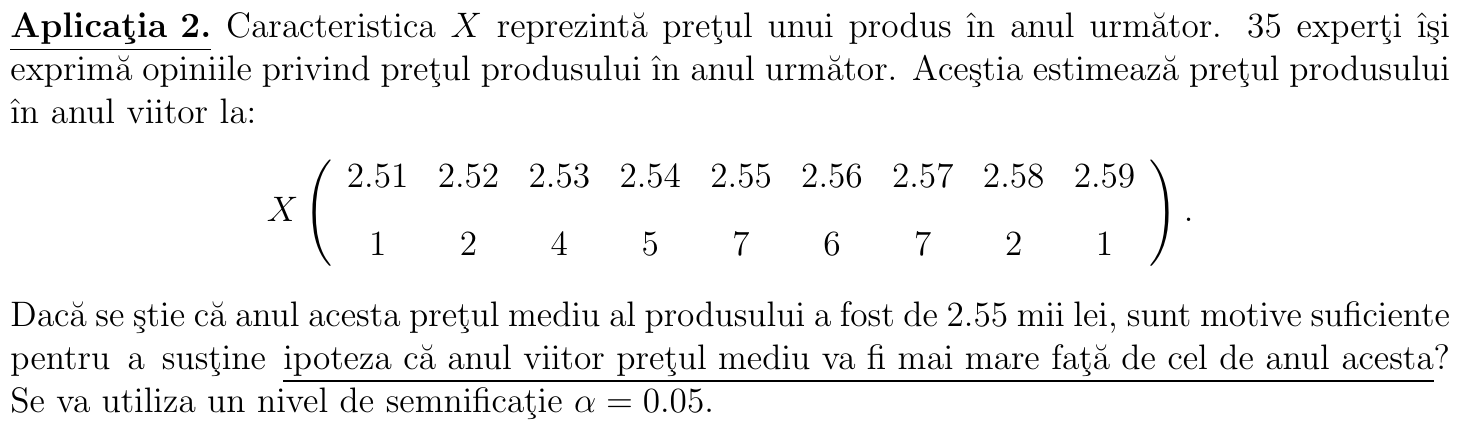

X = [2.51 2.52 2.52 2.53 2.53 2.53 2.53 2.54 2.54 2.54 2.54 2.54 ...
     2.55 2.55 2.55 2.55 2.55 2.55 2.55 2.58 2.58 2.59];
m_0 = 2.55;
alpha = 0.05;
tail = 1;
[h, ~, ~, ~] = ttest(X, m_0, alpha, tail);
if h == 0
    fprintf('Se acceptă ipoteza H_0.')
end

Se acceptă ipoteza H_0.

if h == 1
    fprintf('Se respinge ipoteza H_0.')
end

Din **ttest**, **h = 0**, deci ipoteza $H_0$ se acceptă. Anul viitor, prețul mediu va fi mai mare față de cel de anul acesta.

## Aplicația 3

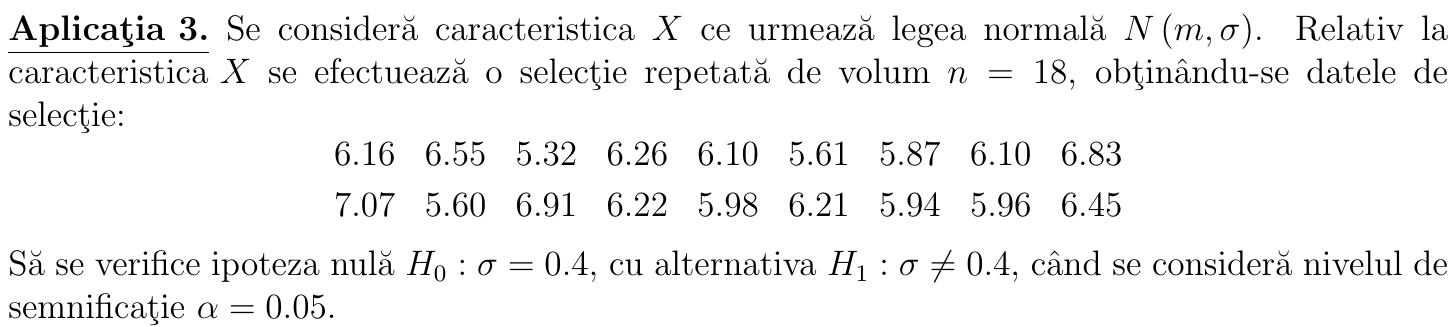

X = [6.16 6.55 5.32 6.26 6.1 5.61 5.87 6.1 6.83 7.07 5.60 6.91 ...
     6.22 5.98 6.21 5.94 5.96 6.45];
n = 18;
sigma_0 = 0.4;
alpha = 0.05;
tail = 0;
[h, ~, ~, ~] = vartest(X, sigma_0^2, alpha, 0);
if h == 0
    fprintf('Se acceptă ipoteza H_0.')
end

Se acceptă ipoteza H_0.

if h == 1
    fprintf('Se respinge ipoteza H_0.')
end

Din **vartest**, **h = 0**, deci se acceptă ipoteza $H_0$. 